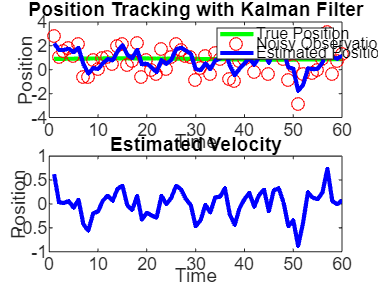

% Time settings
dt = 1; % time step
T = 60; % total time

% State Transition Matrix (A)
A = [1 dt;
    0 1];

% control Matrix (B)
B = [0.5 * dt ^ 2; dt];

%Observation Matrix (H)
H = [1 0]; % We only observe efficiency, not its rate of change

% Process Noise Covariance (Q)
Q = [0.1 0;
    0 0.1];

% Measurement Noise Covariance (R)
R = 1;

% Initial state estimate (efficiency; rate_of_change_of_efficiency)
x = [0.9; 0];  % Starting with an initial guess for efficiency
% Initial error covariance (P)
P = eye(2);

% Generate synthetic data for true efficiency and noisy observations
true_position = 0.9 + 0.05 * sin(0.1 * (1 : T));  % True efficiency (for illustration)

observed_position = true_position + sqrt(R) * randn(1, T);  % Noisy observations

% Kalman Filter for estimating position and velocity
estimated_position = zeros(1, T);
estimated_velocity = zeros(1, T);

for t = 1 : T
    % Prediction step
    x = A * x;  % State prediction (constant rate of change)
    P = A * P * A' + Q;  % Error covariance prediction
    % Kalman Gain calculation
    K = P * H' / (H * P * H' + R);
    % Measurement update step
    z = observed_position(t);  % Current noisy observation (efficiency)
    x = x + K * (z - H * x);  % State update with observation
    P = (eye(2) - K * H) * P;  % Error covariance update
    
    % Store the estimated efficiency
    estimated_position(t) = x(1);
    estimated_velocity(t) = x(2);
end
 
% Plot the results
figure;
subplot(2, 1, 1);
plot(1 : T, true_position, '-g', 'LineWidth', 2); 
hold on;
plot(1 : T, observed_position, 'ro');
plot(1 : T, estimated_position, '-b', 'LineWidth', 2);
legend('True Position', 'Noisy Observations', 'Estimated Position');
title('Position Tracking with Kalman Filter');
xlabel('Time');
ylabel('Position');

subplot(2, 1, 2);
plot(1 : T, estimated_velocity, '-b', 'LineWidth', 2); 
title('Estimated Velocity');
xlabel('Time');
ylabel('Position');